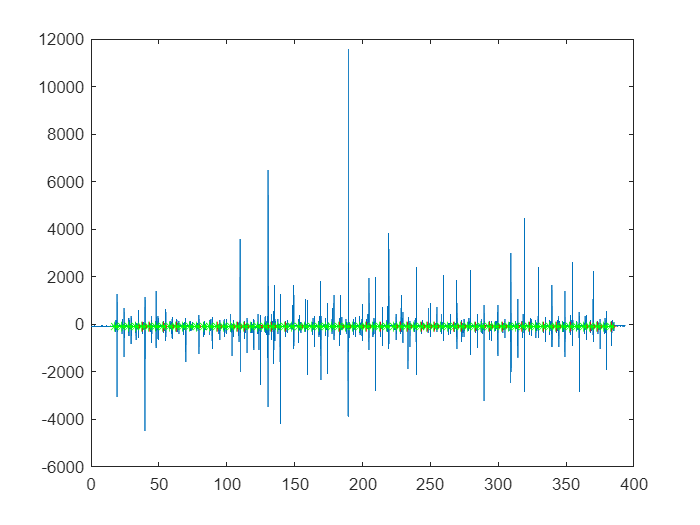

% Script for calculation of starts and ends of movement of a box with IMU sensors during experiments with exoskeleton; Skript Berechnung des Starts und Endes der Bewegung der Kiste für die Exoskelettversuche

% determine folder with data to be evaluated
clear all
[file,path] = uigetfile('*.csv');       % opens dialog window to select file
cd (path);                              % change to selected folder          
M           = readmatrix(file);         % read all data from csv into one matrix
a           = M(1:end,[1,6]);
%a           = M(1:end,[1,4,5,6]);       % acceleration in x,y,z-direction dependent on the time in a matrix with 4 columns (t,x,y,z), importet from csv-file with "Home/import data", see 6.4.2022, folder Dokumente/Versuche Exoskelett

% initialising variables
num_start   = 0;                        % number of start of movement, integer
num_end     = 1;                        % number of end of movement, integer
starts      = 0;                        % initialising start of movement
ends        = 0;                        % initialising end of movement

% parameters for variance
n_start     = 60;                       % number of neighbors after moving value for recognizing movement starts, see function movvar
n_end       = 1000;                     % number of neighbors after moving value for recognizing movement ends, see function movvar
var_start   = movvar(a,2*n_start+1);    % moving variance of 2k+1 neighboring elements of center of moving value of a
var_end     = movvar(a,2*n_end+1);      % moving variance of 101 neighboring elements of center of moving value of a

% calculation of starts and ends of the movement of the box using the variance of the acceleration
for i = n_end+1:length(a)-n_end         % loop over all elements of matrix a
    if  var_start(i+n_start,2) > 700 && var_end(i-n_end,2) < 70 && num_start < num_end% && a(i,1)-starts(num_start+1)>1  % movement starts where change of acceleration is bigger than noise and change of acceleration before was as small as noise and if number of starts of movement smaller than number of ends than a new (num_start+1) movement starts, abs(a(i+1,2) - a(i,2)) > 9
        num_start = num_start+1;
        starts(num_start) = a(i+n_start,1);      % time of start of movement in s
    elseif var_end(i-n_end,2)>150 && abs(var_end(i+n_end,2)) < 150 && num_start >= num_end % movement ends where change of acceleration is as small as noise and change of acceleration before was bigger than noise
        ends(num_end) = a(i,1);                  % time of end of movement in s
         num_end = num_end+1;
    end
end

% plotting of graphs of acceleration and starts and ends of movement and testing it one movement is missing or miscalculated
plot(a(:,1),a(:,2))                             % acceleration in vertical direction over time in mg
y           = a(1,2)*ones(num_start);           % gravity in rest
hold on                                         % plot next graph into same diagram
plot(starts,y,"r+")                             % plot of starts with red +
hold on                                         % plot next graph into same diagram
plot(ends,y,"r.")                               % plot of starts with red dots
hold on                                         % plot next graph into same diagram
ideal_starts       = starts(1):5:starts(end);   % ideally spaced vector with 5-s-steps
plot(ideal_starts,y,"g*")
diff_start = starts - ideal_starts;             % difference between ideal and actual time of start of movement
[t_max_start,num_max_start]=max(diff_start);    % xMax is Maximum of diff, num_max is number of start of maximum
if max(diff_start) > 1
    disp(['Die berechnete Startzeit der Bewegung beim ',num2str(num_max_start),'. Start nach ',num2str(starts(num_max_start)),' s weicht um ',num2str(t_max_start),' s vom idealen Takt ab']) % num2str necessary to display variable
end
ideal_ends       = ends(1):5:ends(end);         % ideally spaced vector with 5-s-steps
plot(ideal_ends,y,"g.")

diff_end = ends - ideal_ends;                   % difference between ideal and actual time of start of movement
[t_max_end,num_max_end]=max(diff_end);          % xMax is Maximum of diff, num_max is number of start of maximum
if max(diff_end) > 1
    disp(['Die berechnete Endzeit der Bewegung beim ',num2str(num_max_end),'. Ende nach ',num2str(ends(num_max_end)),' s weicht um ',num2str(t_max_end),' s vom gleichmäßigen Takt ab']) % num2str necessary to display variable
end

Die berechnete Endzeit der Bewegung beim 23. Ende nach 131.0905 s weicht um 1.598 s vom gleichmäßigen Takt ab



% decide which movement is lifting and which one is lowering
lowering_start  = starts(2*(1:num_start/2)-1);  % first, box is on table, is lowered, everey second movement is lowering (odd numbers)
lifting_start   = starts(2*(1:num_start/2));
lowering_end    = ends(2*(1:num_end/2)-1);      % first, box is on table, is lowered, everey second movement is lowering (odd numbers)
lifting_end     = ends(2*(1:num_end/2));

% writing data into Excel file Testpersonen
filename        = 'C:\Users\fhinz\Documents\Versuche Exoskelett\Testpersonen_test2.xlsx';   % file extension has to be mentioned
columns         = 'ABCDEF';
writematrix(starts',filename,'Sheet',['p',num2str(file(2)),],'Range',[columns(2*str2num(file(3))-1),'2'])    % writes column vector starts' into the file to the sheet named 'p (number of person)' starting with field A2 (number of experiment), file(2) is second digit of filename of input file
writematrix(ends',filename,'Sheet',['p',num2str(file(2)),],'Range',[columns(2*str2num(file(3))),'2'])       % writes column vector ends' into the file to the sheet named 'p...' starting with field A2
